# Correlacion de señales

Obtener o medir la correlacion significa encontrar semejanzas entre dos señales

Ejemplo 1

Creando dos señales de prueba. Es la misma señal con un desplazamiento

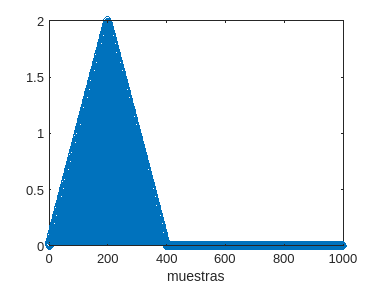

n = 0:999;
xn = zeros(size(n));
xn(1:200) = n(1:200)/100;
xn(201:400) = 2-xn(1:200);

yn1 = circshift(xn,450);

figure()
stem(n,xn)
xlabel("muestras")

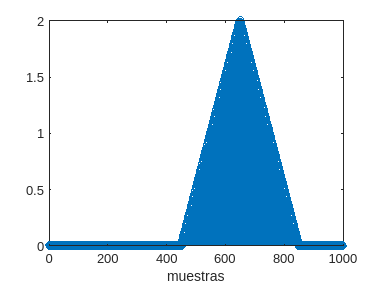

figure()
stem(n,yn1)
xlabel("muestras")

Aplicacion de la correlacion cruzada (xn corr yn1) sobre las señales

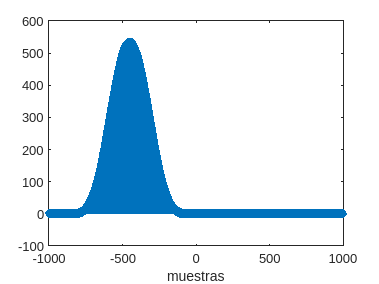

[rxy,lags] = xcorr(xn,yn1);
figure()
stem(lags,rxy)
xlabel("muestras")

Aplicacion de la correlacion cruzada (yn1 corr xn) sobre las señales

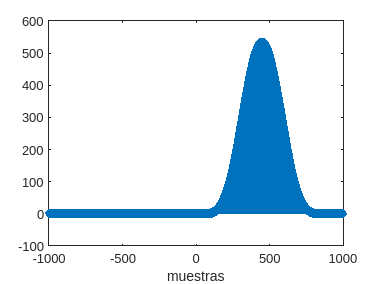

[ryx,lags] = xcorr(yn1,xn);
figure()
stem(lags,ryx)
xlabel("muestras")

Lo anterior demuestra que la correlacion cruzada no es conmutativa